# ACM 11 Homework 4 Part 1

You should read the problem set-up in this file and follow the instructions to write and test your code. This part is independent of Part 2, you can do them in any order. When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas.

**Motivation**

It is of vital importance in the scientific or engineering practice to evaluate integrals like $\int_\Omega f(x)dx$, where $f$ is some function that doesn't necessarily have an analytical form but only supports evaluation, and the region $\Omega \subset {\mathbf{R}}^d$. Even if sometimes people are lucky enough to meet an analytical $f$, we could still have no access to a closed-form formula for the integral (for example, try evaluating $\int_{-\infty}^y e^{-x^2} dx$). 

The numerical solution to such integral $\int_\Omega f(x)dx$ consists of two approached: a deterministic one named numerical quadrature, and a stochastic one called the Monte Carlo method. 

To start with, we clean our Workspace in MATLAB to avoid confusion.

clear

### Problem 1: Numerical Quadrature

Numerical quadrature is a very classic method that estimates the integral $\int_\Omega f(x)dx$ by a weighted sum: $\int_\Omega f(x)dx \approx \sum_{=1,2,...,n}w_i f(x_i)$. The weights $w_i$ and the abscissa $x_i$ are carefully chosen so that the estimate is accurate for a large class of anonymous function $f$. ("Abscissa" is a fancy way to refer to the horizontal coordinate of a graph, and is common in quadrature literature.)

Define out target functions: $f\left(x\right)=e^{x-x^2 \;\sin \left(2x\right)}$ and $g\left(x,y\right)=e^{x^2 +y-\tanh \left(2y\right)}$.

Replace the 0 in the code block below with the appropriate function.

f = @(x) exp(x - x.^2 .* sin(2*x));
g = @(x,y) exp(x.^2 + y - tanh(2*y));

Let the region $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. For dimension $d=1,2$, complete the skeleton code for the Gaussian quadrature rule `GQ`. Here $n$ is the number of abscissas we would have along one dimension. In other words, there are $n^d$ abscissas in total. See the notes/class slides on multivariate integrals for the appropriate formula for approximating a 2D integral.

For $n=2,3,4,5,6,7,8$, compare the output of the `GQ` function with the output of the built-in functions `integral` and `integral2` (for $d=1,2$respectively). You should measure the error of `GQ` with respect to the reference integral value by absolute value, and plot it against the number of total abscissas used (be careful, it should be $n^d$). Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for $x$- and $y$-axes. Include appropriate axes labels and a legend. You may find the function `loglog `helpful.

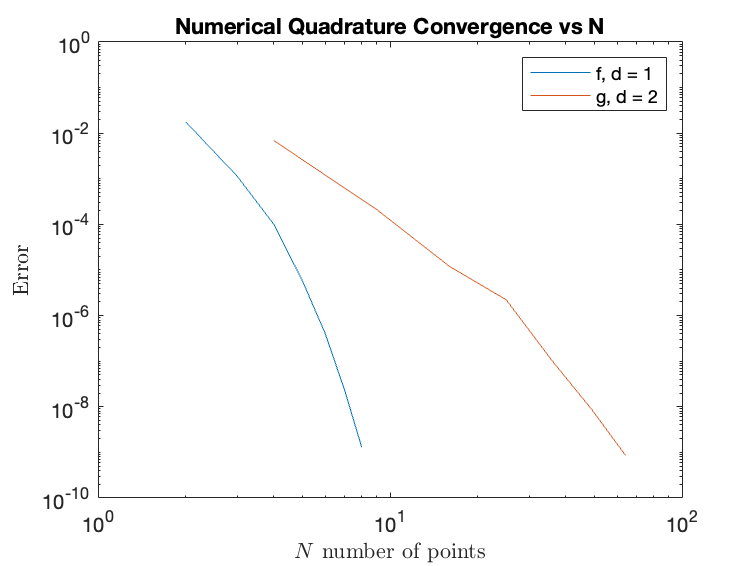

N = [2,3,4,5,6,7,8];
a = 0;
b = 1;

errgaussf = zeros(length(N),1);
errgaussg = zeros(length(N),1);
exactf =  integral(f,a,b);
exactg = integral2(g,a,b,a,b);

for n = 2:8
    estf = GQ(f,1,n);
    estg = GQ(g,2,n);
    errgaussf(n-1) = abs(estf - exactf);
    errgaussg(n-1) = abs(estg - exactg);
end

figure(1); clf
loglog(N,errgaussf);
hold on
loglog(N.^2,errgaussg);
xlabel('$N$ number of points','interpreter','latex'); 
ylabel('Error','interpreter','latex'); 
legend('f, d = 1','g, d = 2'); 
title('Numerical Quadrature convergence vs N');

How does the convergence of the quadrature estimate the integral (slope of the error) differ between these two functions? Explain your observation in terms of the integral dimension $d$.

The convergence between these two functions such that the estimate for function $f$ converges for about 10 times fewer points than $g$.  This makes sense since $g$ requires $N^2$ points since it is of dimension $d=2$ vs $d=1$ for $f$.  Both estimates follow a similar convergence path, with a smaller slope for lower values of N and a steeper slope for higher values of N. 

### Problem 2: Monte Carlo Estimate

Another approach to estimate the integral $\int_\Omega f(x)dx$ is to write it as in the expectation form: $\int_\Omega f(x)dx = |\Omega| {\bf E}_{u\sim U(\Omega)}[f(u)]$, here $|\Omega |$ is the length/area/volume of the region $\Omega$, and $u$ is a random variable that is uniformly distributed on $\Omega$. Then, we can use the Monte Carlo method to estimate this expectation. Let $u_1 ,\ldotp \ldotp \ldotp ,u_n$ be the i.i.d. samples from the uniform distribution on $\Omega$, then ${\bf E}_{u\sim U(\Omega)}[f(u)]\approx \frac{1}{n} \sum_{i=1,2,...,n}f(u_i)$. Thus we conclude that $\int_\Omega f(x) dx \approx \frac{|\Omega|}{n}\sum_{i=1,2,...,n}f(u_i)$. 

Write a function named `MCE` that takes in the function $f$, dimension $d$, and number of samples $n$, and outputs the Monte Carlo estimate. Here we assume that $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. You may use `rand` to generate a random variable uniformly distributed between 0 and 1.

**Complete the **`MCE`** function at the bottom of this file with the appropriate function.**

For $n=10,100,1000,10000$, compare the output of the `MCE` function with the built-in functions `integral` and `integral2` (for $d=1,2$ respectively). Due to the randomness, for each $n$, we want you to call `MCE` for $100$ times, and use the mean of their absolute difference with respect to the reference integral value as the error. You may find the function `mean` helpful. Plot the error against the number of total samples used. Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for both $x$- and $y$-axes. You may find the function `loglog `helpful.

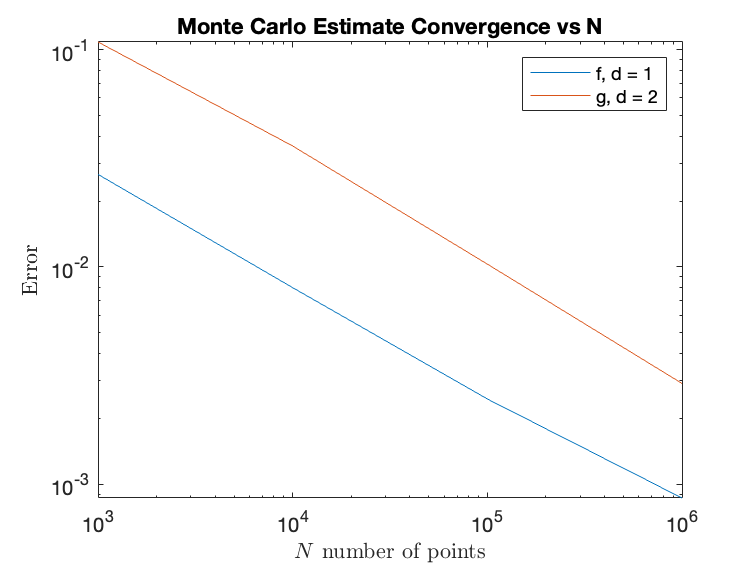

N = [10,100,1000,10000];

errmcef = zeros(4,1);
errmceg = zeros(4,1);

for i = 1:4
    mcef = 0;
    mceg = 0;
    for j = 1:100
        mcef = mcef + abs(MCE(f,1,N(i)) - exactf);
        mceg = mceg + abs(MCE(g,2,N(i)) - exactg);
    end
    errmcef(i) = mcef/100;
    errmceg(i) = mceg/100;
end

figure(2); clf
loglog(N*100,errmcef);
hold on
loglog(N*100,errmceg);
xlabel('$N$ number of points','interpreter','latex'); 
ylabel('Error','interpreter','latex'); 
legend('f, d = 1','g, d = 2'); 
title('Monte Carlo estimate convergence vs N');

How does the convergence of the Monte Carlo estimate of the integral (slope of the error) behave for these two functions? How is this different from the convergence behavior of the traditional quadrature approach? Is this theoretically expected?

The Monte Carlo estimate of the integral behaves very similar for $f$ and $g$.  Both decrease semi-log linearly such that as N increases 10-fold, we observe a decrease in error for both functions of about 5-fold.  Additionally, we observe convergence of $f$for $N={10}^6$, but do not observe convergence of $g$ within this amount of points.  This is different from the traditional quadrature approach as it takes a much higher number of points to reach convergence for both functions, although the log-linearity is mostly preserved.  Additionally, we do not observe the same sort of relationship between dimension and convergence rate, we only have that convergence of $g\;$takes longer than $f$, but not twice as long.  This is theoretically expected as our rate of convergence should not depend on the dimension of our function for MCE.

function I = MCE(func,d,n)
assert(d==1|d==2,"Invalid dimension")

X = rand([d n]);

if d == 1
    fX = func(X);
    I = sum(fX)/n;
else
    fX1 = X(1,:);
    fX2 = X(2,:);
    fX = func(fX1,fX2);
    I = sum(fX)/n;
end

end

Please report the number of hours you spent on this part of the homework: 4 hours